Get model Unified Model of GFMI

close all
clear all
clc

run("Parameters.m")
load('Unified_CGVSG.mat');

GFMI_1 = Unified_GFMI;

SCR and X/R ratio is a special case where the operating point should be computed for each variation.

We need the grid impedance for the range of SCR

Range=logspace(log10(0.5),log10(20),10);
Range=linspace(0.5,12,10);
SweepVariable="XR";
VariableLabel="XR";
Rg_vec = zeros(1, length(Range));Lg_vec = zeros(1, length(Range));
for i = 1:length(Range)
    XR = Range(i); 

    %% You need to change this Zb and Lb values
    Lb = load("Parameters.mat", 'Lb').Lb; 
    SCR = load("Parameters.mat", 'SCR').SCR;

    Rgpu = 1 / (SCR * sqrt(1 + XR^2));
    Lgpu = XR * Rgpu;

    Rg_vec(i) = Rgpu * load("Parameters.mat", 'Zb').Zb; 
    Lg_vec(i) = Lgpu * Lb;
end

We compute the power flow and the linear operating point for each variation of grid impedance. 

We then build models for the different variations and store it in a structured file that we will later use to substitute the rest of the static parameters.

%addpath('C:\Users\sali0043\matpower8.0');
%savepath;

V_LL=load("Parameters.mat","V_LL").V_LL;
rf2=load("Parameters.mat","rf2").rf2;lf2=load("Parameters.mat","lf2").lf2;

% Pre-allocate arrays for storing results
Angle   = zeros(1, length(Range));Voltage_mag = zeros(1, length(Range));
Vpcc_D0 = zeros(1, length(Range));Vpcc_Q0 = zeros(1, length(Range));
Vc_d0   = zeros(1, length(Range));Vc_q0   = zeros(1, length(Range));
i2_d0   = zeros(1, length(Range));i2_q0   = zeros(1, length(Range));
delta0  = zeros(1, length(Range));
% Initialize as cell arrays
A_Stage1 = cell(1, length(Range));B_Stage1 = cell(1, length(Range));C_Stage1 = cell(1, length(Range));D_Stage1 = cell(1, length(Range));
for i = 1:length(Range)

    mpc = SMIB_PowerFlow(Rg_vec(i),Lg_vec(i));  
    % Optionally, insert code here to modify mpc fields based on Rg and Lg.
    
    % Run the power flow for this operating point
    PowerFlow_results = runpf(mpc);
    
    % Extract bus 1 angle (in degrees) and voltage magnitude (p.u)
    Angle(i) = PowerFlow_results.bus(1,9);
    Voltage_mag(i) = PowerFlow_results.bus(1,8);
    
    % Calculate space phasors
    Angle_rad = deg2rad(Angle(i));
    Vc_phasor = Voltage_mag(i) * V_LL/sqrt(3) * exp(1j * Angle_rad); % line-to-neutral voltage
    Vg_phasor = V_LL/sqrt(3);
    
    % Compute impedance values (assuming these parameters are constant)
    Zt = (rf2 + Rg_vec(i) + 1j * 2*pi*50 * (lf2 + Lg_vec(i)));
    Z2 = rf2 + 1j * 2*pi*50 * lf2;
    
    % Calculate current and PCC voltage phasors
    I2_phasor = (Vc_phasor - Vg_phasor) / Zt;
    Vpcc_phasor = (Vc_phasor - I2_phasor * Z2) * sqrt(2);
    
    % Store operating point values
    delta0(i) = Angle_rad;    
    Vpcc_D0(i) = real(Vpcc_phasor);
    Vpcc_Q0(i) = imag(Vpcc_phasor);
    
    % Transform Vc phasor into d–q components
    Vc_dq0 = Vc_phasor * exp(-1j * Angle_rad) * sqrt(2);
    Vc_d0(i) = real(Vc_dq0);
    Vc_q0(i) = imag(Vc_dq0);
    
    % Transform I2 phasor into d–q components
    I2_dq0 = I2_phasor * exp(-1j * Angle_rad) * sqrt(2);
    i2_d0(i) = real(I2_dq0);
    i2_q0(i) = imag(I2_dq0);

    %Make model for each variation
    A_Stage1{1,i} = subs(GFMI_1.sym_A, {'rg','lg','delta0','Vpcc_D0','Vpcc_Q0','Vc_d0','Vc_q0','i2_d0','i2_q0'},{Rg_vec(i), Lg_vec(i), delta0(i), Vpcc_D0(i), Vpcc_Q0(i), Vc_d0(i), Vc_q0(i), i2_d0(i), i2_q0(i)});
end


MATPOWER Version 8.0, 17-May-2024
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

Converged in 0.26 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              2     Total Gen Capacity     999.0        -999.0 to 999.0
Generators         1     On-line Capacity       999.0        -999.0 to 999.0
Committed Gens     1     Generation (actual)     -0.9               0.1
Loads              1     Load                    -1.0              -0.0
  Fixed            1       Fixed                 -1.0              -0.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0

We substitute the rest of the static grid parameters

load("Parameters.mat")

for i = 1:length(Range)
    A_Stage2{i}=double(subs(A_Stage1{1,i}));
    B_Stage2{i}=double(subs(B_Stage1{1,i}));
    C_Stage2{i}=double(subs(C_Stage1{1,i}));
    D_Stage2{i}=double(subs(D_Stage1{1,i}));
    GFMI_2{i}=ss(A_Stage2{i}, B_Stage2{i}, C_Stage2{i}, D_Stage2{i});
end


# Benchmark GFMI

load("Parameters.mat")

mpc = SMIB_PowerFlow(rg,lg);  
% Optionally, insert code here to modify mpc fields based on Rg and Lg.

% Run the power flow for this operating point
PowerFlow_results = runpf(mpc);


MATPOWER Version 8.0, 17-May-2024
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

Converged in 0.09 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              2     Total Gen Capacity     999.0        -999.0 to 999.0
Generators         1     On-line Capacity       999.0        -999.0 to 999.0
Committed Gens     1     Generation (actual)     -1.0               0.2
Loads              1     Load                    -1.0              -0.0
  Fixed            1       Fixed                 -1.0              -0.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0


% Extract bus 1 angle (in degrees) and voltage magnitude (p.u)
Angle(i) = PowerFlow_results.bus(1,9);
Voltage_mag(i) = PowerFlow_results.bus(1,8);

% Calculate space phasors
Angle_rad = deg2rad(Angle(i));
Vc_phasor = Voltage_mag(i) * V_LL/sqrt(3) * exp(1j * Angle_rad); % line-to-neutral voltage
Vg_phasor = V_LL/sqrt(3);

% Compute impedance values (assuming these parameters are constant)
Zt = (rf2 + rg + 1j * 2*pi*50 * (lf2 + lg));
Z2 = rf2 + 1j * 2*pi*50 * lf2;

% Calculate current and PCC voltage phasors
I2_phasor = (Vc_phasor - Vg_phasor) / Zt;
Vpcc_phasor = (Vc_phasor - I2_phasor * Z2) * sqrt(2);

% Store operating point values
delta0 = Angle_rad;    
Vpcc_D0 = real(Vpcc_phasor);
Vpcc_Q0 = imag(Vpcc_phasor);

% Transform Vc phasor into d–q components
Vc_dq0 = Vc_phasor * exp(-1j * Angle_rad) * sqrt(2);
Vc_d0 = real(Vc_dq0);
Vc_q0 = imag(Vc_dq0);

% Transform I2 phasor into d–q components
I2_dq0 = I2_phasor * exp(-1j * Angle_rad) * sqrt(2);
i2_d0 = real(I2_dq0);
i2_q0 = imag(I2_dq0);

%Make model for each variation
A_Benchmark = double(subs(GFMI_1.sym_A));
Benchmark_Poles=eig(A_Benchmark);

# Generate Figures

%% Define scaling and dimensions
scale = 2;
Figure_width  = 7.98;   % saved width (cm)
Figure_height = 4.2;    % saved height (cm)
Main_Figure_pos = scale * [0, 0, Figure_width, Figure_height]; 
color_palet = colormap(turbo(length(Range))); % Generate the color palette

## Main figure settings

Main_Figure = figure();
set(Main_Figure, 'Units', 'centimeters', 'Position', Main_Figure_pos);
Pole_axes_pos = scale * [1, 0.75, Figure_width*0.5, Figure_height*0.75];
Pole_axes = axes('Units', 'centimeters', 'Position', Pole_axes_pos);
hold(Pole_axes, 'on');
for i = 1:length(Range)
    A = GFMI_2{i}.A;
    Poles = eig(A);
    plot(Pole_axes, real(Poles), imag(Poles), 'x', 'MarkerSize', 4, 'LineWidth', 1, 'Color', color_palet(i, :));
end

% Plot the benchmark poles with labels
for k = 1:length(Benchmark_Poles)
    text(Pole_axes,real(Benchmark_Poles(k)), imag(Benchmark_Poles(k)),sprintf('$$\\lambda_{%d}$$', k),'Color', 'black'); % Add lambda number as text
end

xline(Pole_axes, 0, 'k--', 'LineWidth', 1);
axis(Pole_axes, [-40, 10, -500, 500]);
set(Pole_axes, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '--', 'GridColor', 'k');
xlabel(Pole_axes, '$$\sigma$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'top','HorizontalAlignment', 'center');
ylabel(Pole_axes, '$$j \omega$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'baseline','HorizontalAlignment', 'center');

## Color settings

colormap(turbo(length(Range)));
clim([min(Range), max(Range)]); % Set the color axis range
cb = colorbar(Pole_axes);
cb.Location="northoutside"

cb =   ColorBar with properties:

    Location: 'northoutside'
      Limits: [0.5000 12]
    FontSize: 9
    Position: [0.1250 0.7770 0.5011 0.0550]
       Units: 'normalized'

  Show all properties


cb.Ticks = round([linspace(min(Range), max(Range), 4)],1);
cb.Label.String = '$$\frac{X}{R}$$';cb.Label.Interpreter = 'latex';
cb.Label.VerticalAlignment='baseline';

## Zoomed 1 figure settings

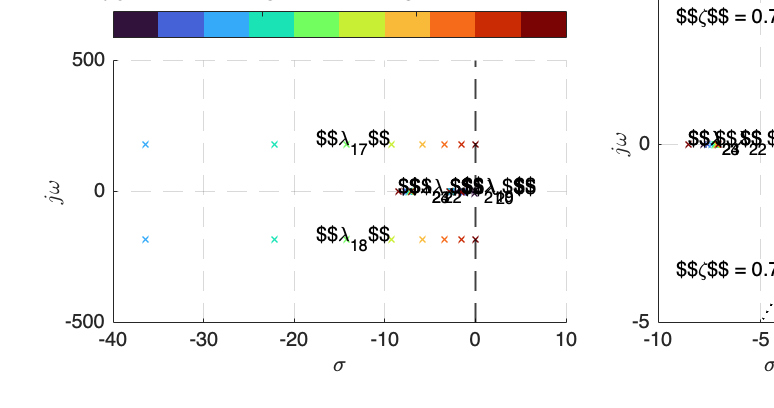

Zoom1_axes_pos = scale * [5.8, 0.75, Figure_width*0.25, Figure_height*0.75];
Zoom1_axes = axes('Units', 'centimeters', 'Position', Zoom1_axes_pos);
hold(Zoom1_axes, 'on');
for i = 1:length(Range)
    A = GFMI_2{i}.A;
    Poles = eig(A);
    plot(Zoom1_axes, real(Poles), imag(Poles), 'x', 'MarkerSize', 4, 'LineWidth', 1, 'Color', color_palet(i, :));
end

% Plot the benchmark poles with labels
for k = 1:length(Benchmark_Poles)
    text(Zoom1_axes,real(Benchmark_Poles(k)), imag(Benchmark_Poles(k)),sprintf('$$\\lambda_{%d}$$', k),'Color', 'black'); % Add lambda number as text
end


add_damping_ratio_lines(5);

xline(Zoom1_axes, 0, 'k--', 'LineWidth', 1);
axis(Zoom1_axes, [-10, 1, -5, 5]);
set(Zoom1_axes, 'XGrid', 'on', 'YGrid', 'on', 'GridLineStyle', '--', 'GridColor', 'k');
xlabel(Zoom1_axes, '$$\sigma$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'top','HorizontalAlignment', 'center');
ylabel(Zoom1_axes, '$$j \omega$$', 'FontWeight', 'bold', 'Interpreter', 'latex', 'VerticalAlignment', 'baseline','HorizontalAlignment', 'center');

## Saving settings

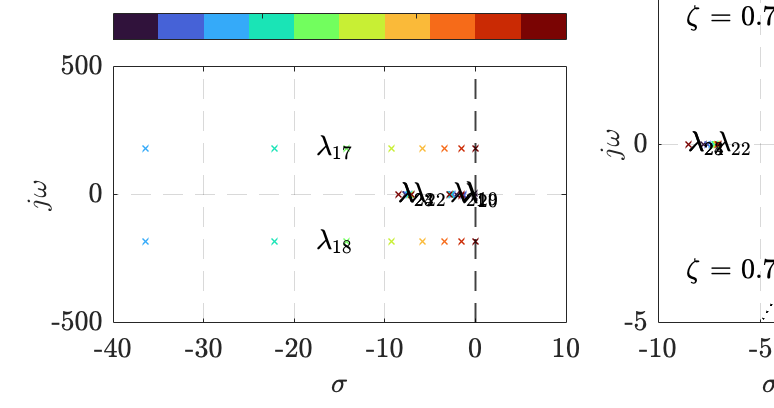

fname = sprintf('CGVSG_%s_EA', VariableLabel);
set(findall(Main_Figure,'-property','FontSize'),'FontSize',14)
set(findall(Main_Figure, '-property', 'FontName'), 'FontName', 'Times New Roman');
set(findall(Main_Figure, '-property', 'Box'), 'Box', 'on');
set(findall(Main_Figure, '-property', 'Interpreter'), 'Interpreter', 'latex');
set(findall(Main_Figure, '-property', 'font'), 'Interpreter', 'latex');
set(findall(Main_Figure, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex');
% 
% %% Set up paper properties for saving
% % Switch from auto to manual paper positioning so that the saved file uses
set(Main_Figure, 'PaperPositionMode', 'manual');
set(Main_Figure, 'PaperUnits', 'centimeters');
set(Main_Figure, 'PaperPosition', Main_Figure_pos);
set(Main_Figure, 'PaperSize', [Main_Figure_pos(3) Main_Figure_pos(4)]);
% 
%% Save the figure
% print(Main_Figure, fname, '-dpng', '-r1000');
print(Main_Figure, '-vector','-dsvg', [fname, '.svg'])

## Damping Ratio fcn

function add_damping_ratio_lines(text_radius)
    angle_degrees = [-45, 45];  % Angles for damping ratio lines

    max_radius = max(abs([xlim, ylim]));  % Use the maximum absolute value of axis limits

    hold on;

    for i = 1:length(angle_degrees)
        angle = angle_degrees(i);
        zeta = cosd(angle);  % Damping ratio (cosine of the angle)

        A = cosd(angle);  % Real axis component
        O = sind(angle);  % Imaginary axis component

        % Generate the damping line
        x = linspace(0, -max_radius * A, 100);  % Negative real axis
        y = linspace(0, max_radius * O, 100);  % Positive imaginary axis

        plot(x, y, 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');  % Dashed black line

        % Add damping ratio text if text_radius is not zero
        if text_radius ~= 0
            x_text = -A * text_radius;
            y_text = O * text_radius;

            text(x_text, y_text, sprintf('$$\\zeta$$ = %3.2f', zeta),  'Color', 'k','HorizontalAlignment', 'right');
        end
    end
end